# 1117课堂内容

## 矩阵运算的补充和多项式的使用

### 一、矩阵运算的补充

tips : 默认列优先

A = [1,2,3;4,5,6;7,8,9]

A =      1     2     3
     4     5     6
     7     8     9


% 元素按列进行求积
prod(A)

ans =     28    80   162


prod(A,2) % 算行的积

ans =      6
   120
   504


% 求累和
cumsum(A)

ans =      1     2     3
     5     7     9
    12    15    18


cumsum(A,2)

ans =      1     3     6
     4     9    15
     7    15    24


% 求累积
cumprod(A)

ans =      1     2     3
     4    10    18
    28    80   162


cumprod(A,2)

ans =      1     2     6
     4    20   120
     7    56   504


% 求平均值
mean(A)

ans =      4     5     6


mean(A,2)

ans =      2
     5
     8


% 求中值
median(A)

ans =      4     5     6


median(A,2)

ans =      2
     5
     8


% 求标准差
std(A)

ans =      3     3     3


std(A,0,2)

ans =      1
     1
     1


% 元素的差分
A = [1,2,3;4,5,6;7,8,9]

A =      1     2     3
     4     5     6
     7     8     9


diff(A)

ans =      3     3     3
     3     3     3


diff(A,1,1)

ans =      3     3     3
     3     3     3


diff(A,1,2)

ans =      1     1
     1     1
     1     1


% 相关系数
% R = corrcoef(A)返回A的相关系数的矩阵，其中A的列表示随机变量
% ，行表示观测值
% R = corroef(A,B)返回两个随机变量A和B之间的系数

### 二、稀疏矩阵

**稀疏矩阵存储效率对比**

tic
A = sprand(2000,3000,0.1);
toc

历时 0.064197 秒。



tic
B = full(A);
toc

历时 0.017871 秒。


**稀疏矩阵的生成**

% S = sparse(A) 
% 通过挤出任何零元素将满矩阵转换为稀疏格式。
% 如果矩阵包含许多0，将矩阵转换位稀疏存储空间可以节省内存
% S = sparse(m,n)
% 生成mxn全0稀疏矩阵

% S = sparese(i,j,v)
% 根据三元组生成稀疏矩阵S
D = sparse(1:10,1:10,1:10)

D =    (1,1)        1
   (2,2)        2
   (3,3)        3
   (4,4)        4
   (5,5)        5
   (6,6)        6
   (7,7)        7
   (8,8)        8
   (9,9)        9
  (10,10)      10


% S = sparse(i,j,v,m,n)
% 将S的大小指定为mxn
% S = sparse(i,j,v)指定行下标为v
F = sparse(1:10,1:10,3)

F =    (1,1)        3
   (2,2)        3
   (3,3)        3
   (4,4)        3
   (5,5)        3
   (6,6)        3
   (7,7)        3
   (8,8)        3
   (9,9)        3
  (10,10)       3


**稀疏矩阵的转换**

A = [1,0,0,0;0,5,0,0;2,0,0,6];
S = sparse(A)

S =    (1,1)        1
   (3,1)        2
   (2,2)        5
   (3,4)        6


B = full(S)

B =      1     0     0     0
     0     5     0     0
     2     0     0     6


C = full(sparse(1:5,1:5,1:5))

C =      1     0     0     0     0
     0     2     0     0     0
     0     0     3     0     0
     0     0     0     4     0
     0     0     0     0     5


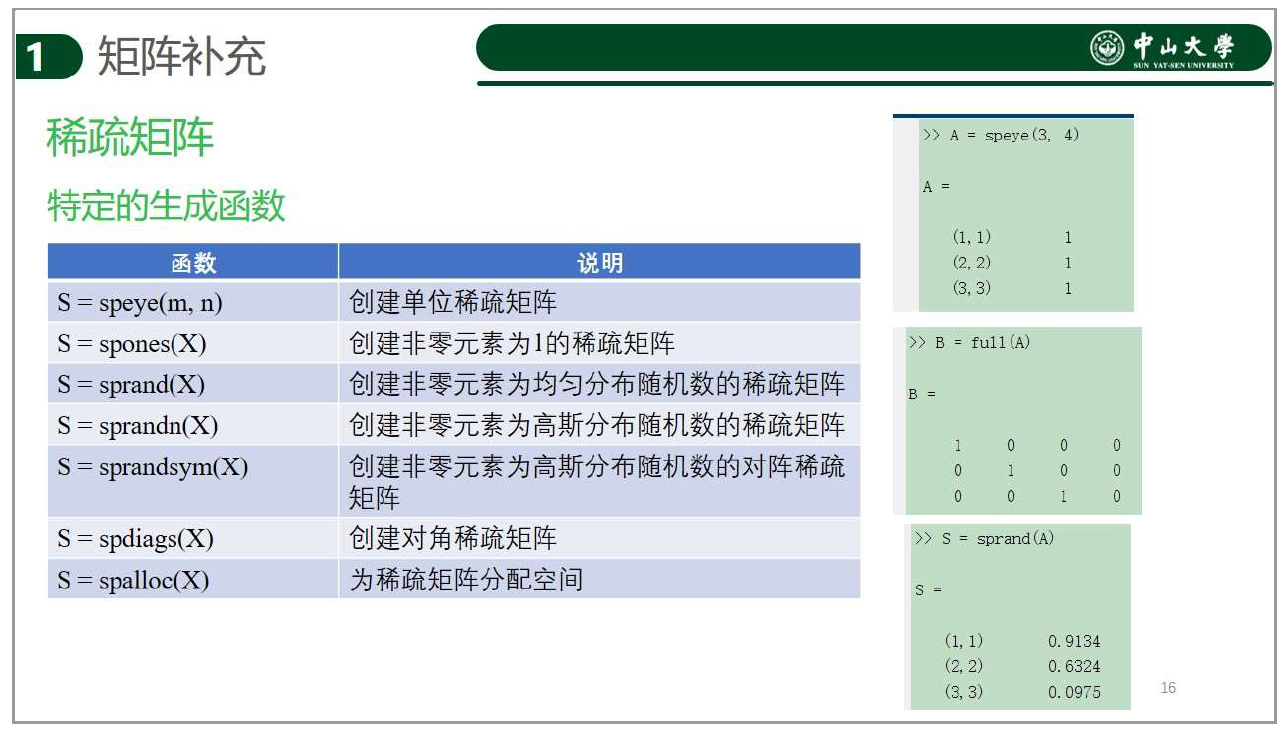

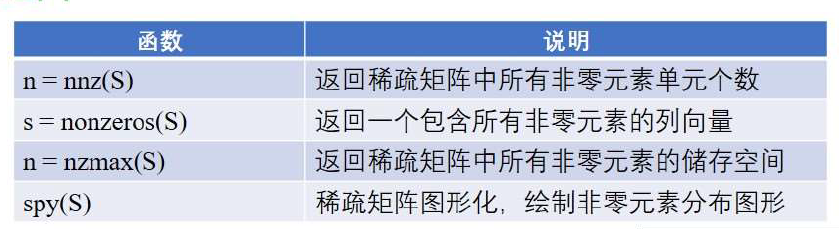

**稀疏矩阵的运算原则**

多个矩阵输入时，如果其中至少有一个矩阵是满矩阵，那么大部分函数的输出结果是满矩阵

对于矩阵的加减乘除运算，只要有一个是满矩阵，那么数据结果都是满矩阵

稀疏矩阵的数乘和幂都是稀疏矩阵、

### 三、矩阵分解

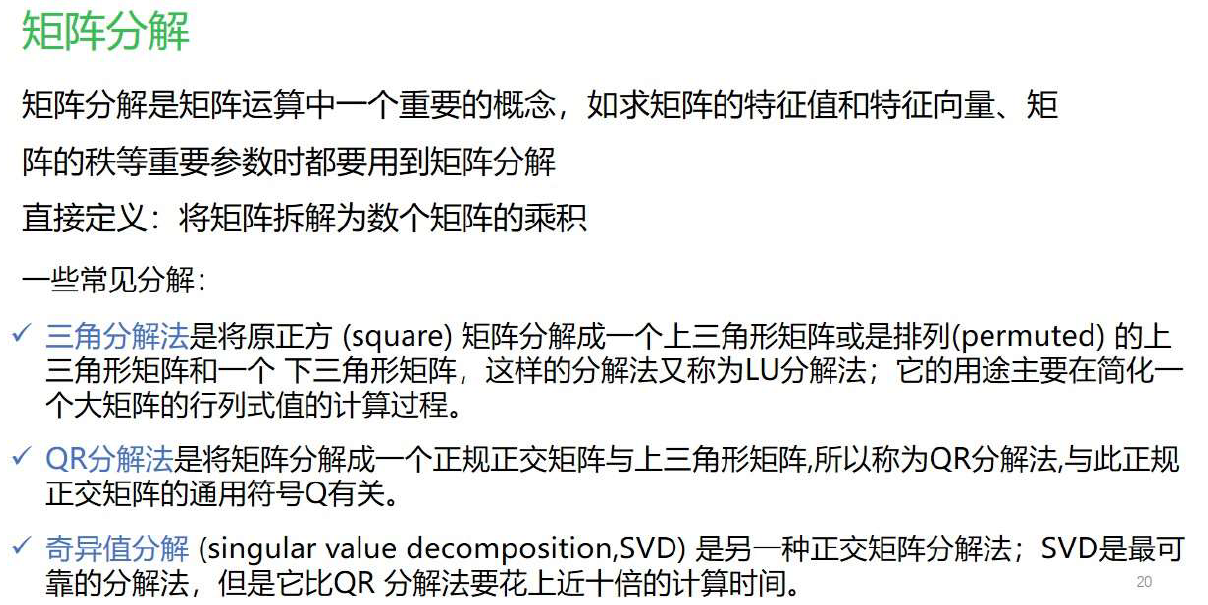

**三角分解(LU分解)**

或者称为高斯消去法；

将一个任意方阵A分解为一个下三角矩阵L和一个上三角矩阵U的乘积

即 A = LU

A = [1,2,3;4,5,6;7,8,9];
[L,U] = lu(A);
L,U

L =     0.1429    1.0000         0
    0.5714    0.5000    1.0000
    1.0000         0         0


U =     7.0000    8.0000    9.0000
         0    0.8571    1.7143
         0         0   -0.0000


**正交分解(QR分解)**

对于非奇异矩阵A(nxn)，存在正交矩阵Q和上三角矩阵R使得

A = QxR ，QR的分解是唯一的。

A = [1,2,3;4,5,6;7,8,9];
[Q,R]=qr(A);
Q,R

Q =    -0.1231    0.9045    0.4082
   -0.4924    0.3015   -0.8165
   -0.8616   -0.3015    0.4082


R =    -8.1240   -9.6011  -11.0782
         0    0.9045    1.8091
         0         0   -0.0000


**奇异值分解(SVD分解)**

利用mxn矩阵A的特征值和奇异值进行分解

A = [1,2,3;4,5,6;7,8,9];
[U,S,V] = svd(A);
U,S,V

U =    -0.2148    0.8872    0.4082
   -0.5206    0.2496   -0.8165
   -0.8263   -0.3879    0.4082


S =    16.8481         0         0
         0    1.0684         0
         0         0    0.0000


V =    -0.4797   -0.7767    0.4082
   -0.5724   -0.0757   -0.8165
   -0.6651    0.6253    0.4082


**特征分解**

对于N阶方阵A，特征值为λ1....λN，有AV=VA

如果V线性无关，则V可逆，此时$A=V\Lambda V^{-1}$称为A的特征解，对角阵$\Lambda$称为A的标准型。

A = [1,2,3;4,5,6;7,8,9];
[V,D] = eig(A);
V,D

V =    -0.2320   -0.7858    0.4082
   -0.5253   -0.0868   -0.8165
   -0.8187    0.6123    0.4082


D =    16.1168         0         0
         0   -1.1168         0
         0         0   -0.0000


### 四、多项式的创建和使用

在matlab中，提供了poly2sym函数实现多项式的构造

% r = poly2sym(p) p为多项式的系数向量
% r = poly2sym(p,v) p为多项式的系数向量，v为其变量
a = poly2sym([1,2,3,4])

$$a = x^{3}+2\,x^{2}+3\,x+4$$

t = sym('t')

$$t = t$$

b = poly2sym([1,2,3,4],t)

$$b = t^{3}+2\,t^{2}+3\,t+4$$

#### 使用

a = [1,2,4,7];
b = [1,4,6,12];
d = a+b;
poly2sym(d)

$$ans = 2\,x^{3}+6\,x^{2}+10\,x+19$$

c = [1,2,-6,10,0,99];
d

d =      2     6    10    19


e2 = c + [0,0,d] % 注意：这里要补齐首0

e2 =      1     2    -4    16    10   118


% 不补0的话运算会有误

**多项式乘法**

% c = conv(a,b) % 执行两个向量的卷积运算
u = [1,0,1];
v = [2,7];
w = conv(u,v);
poly2sym(w)

$$ans = 2\,x^{3}+7\,x^{2}+2\,x+7$$

% c = conv(a,b,shape) 按照参数shape返回卷积运算
% 可选：
% full:完整卷积：即默认值
% same:返回部分卷积，大小与向量a大小相等
% valid:只返回无填充0部分的卷积
u = [-1,2,3,-2,0,1,2];
v = [2,4,-1,-1];
conv(u,v)

ans =     -2     0    15     7   -13     1    10     7    -3    -2


conv(u,v,'same')

ans =     15     7   -13     1    10     7    -3


**多项式除法**

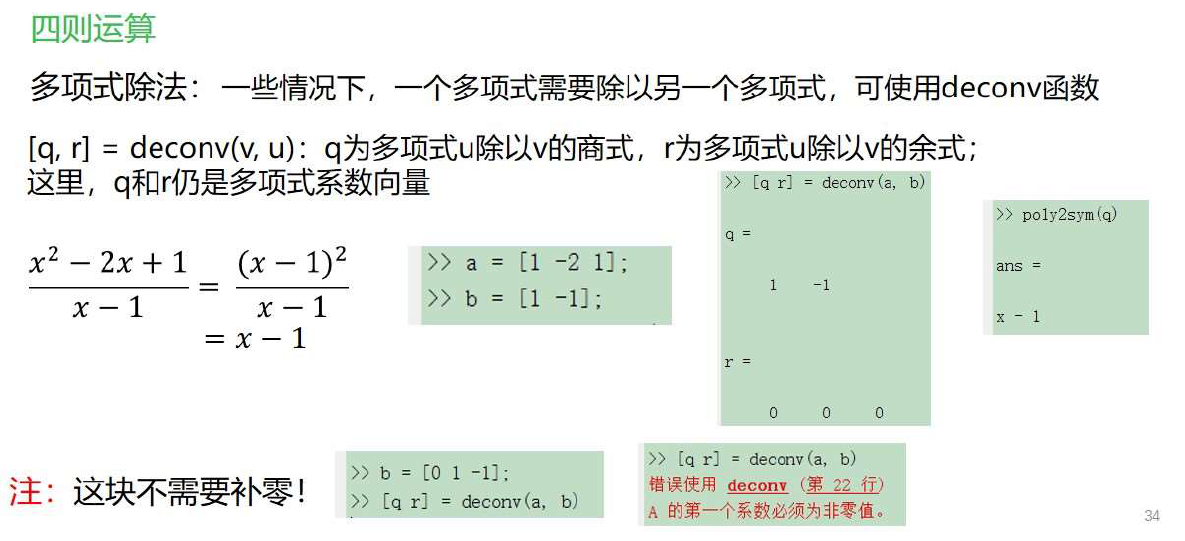

% [q,r]
% q为多项式u/v的商式，r为u/v的余式
% q和r仍是多项式系数向量
a = [1,-2,1];
b = [1,-1];
[q,r] = deconv(a,b)

q =      1    -1


r =      0     0     0


poly2sym(q)

$$ans = x-1$$

**求导**

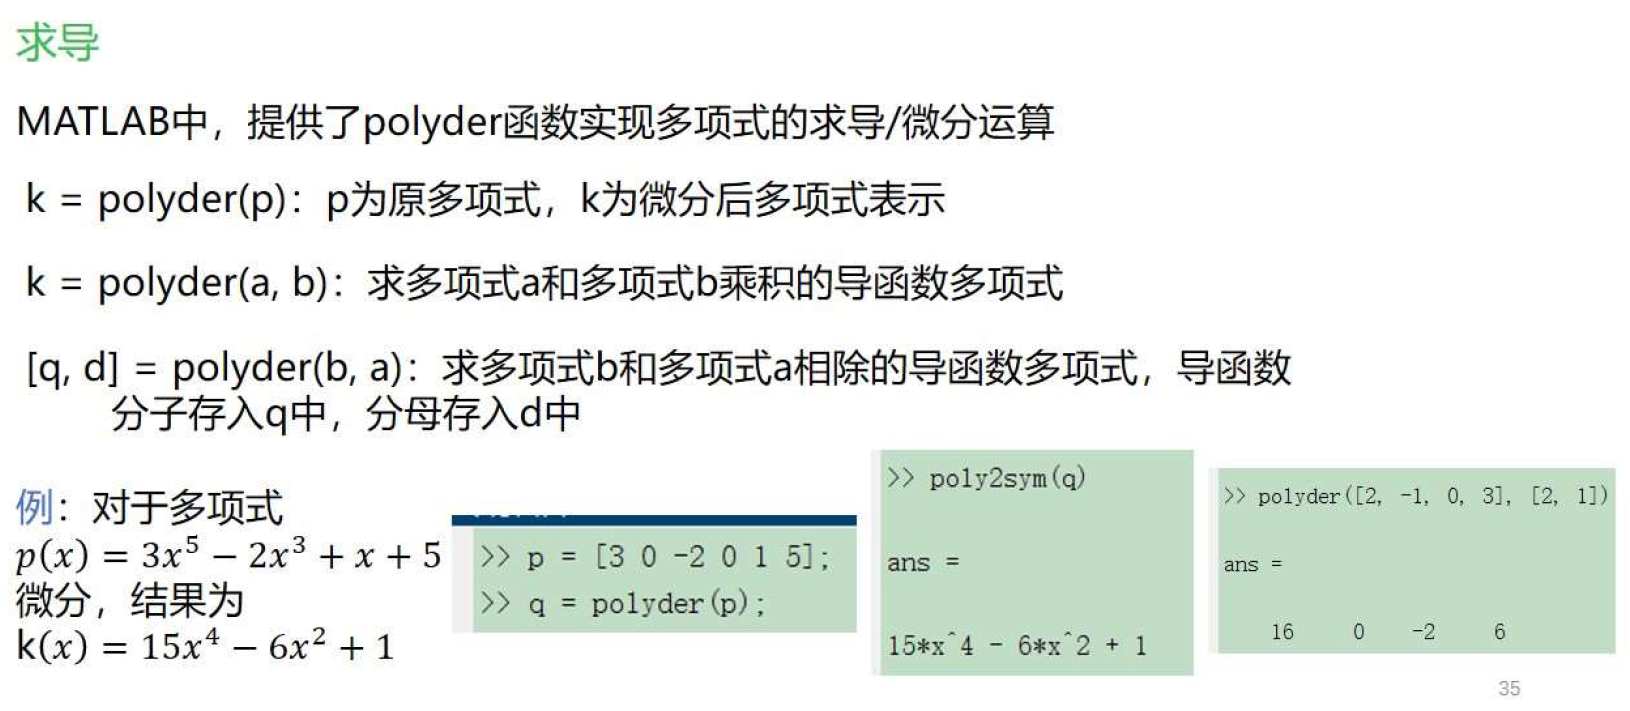

p = [3,0,-2,0,1,5];
poly2sym(p)

$$ans = 3\,x^{5}-2\,x^{3}+x+5$$

q = polyder(p)

q =     15     0    -6     0     1


poly2sym(q)

$$ans = 15\,x^{4}-6\,x^{2}+1$$

**积分**

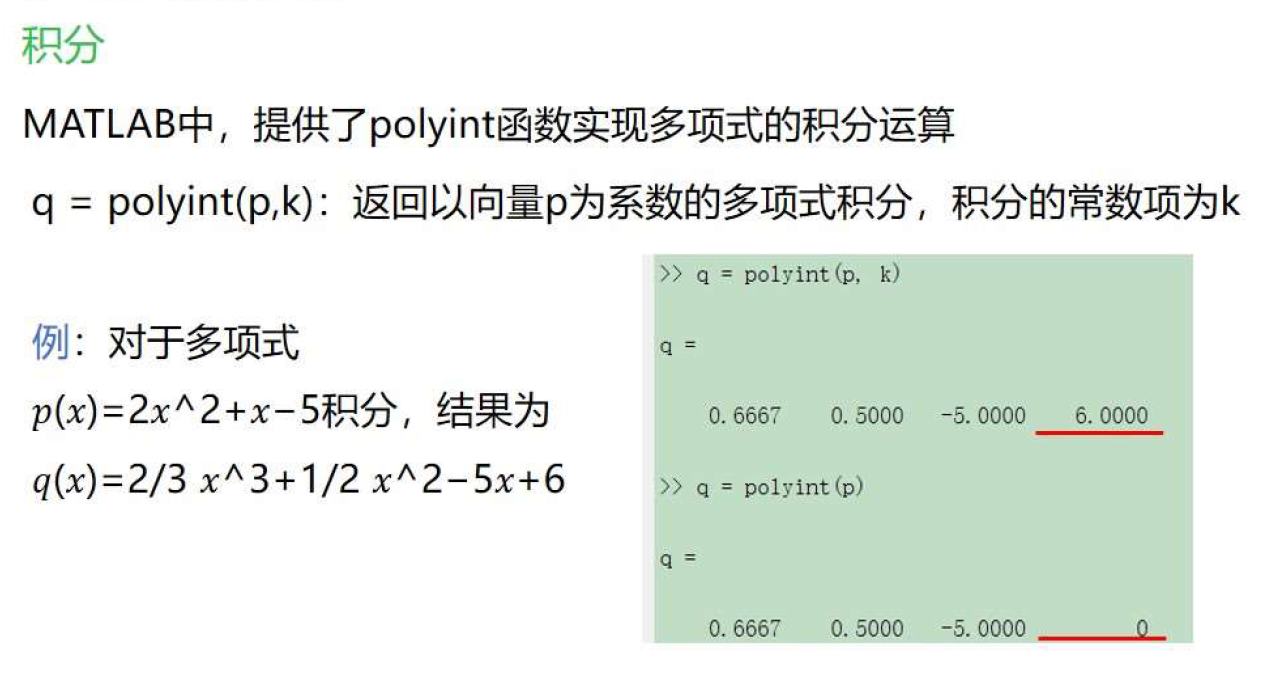

p = [2,1,-5];
poly2sym(p)

$$ans = 2\,x^{2}+x-5$$

% k是积分常数
k = 1;
q = polyint(p,k);
poly2sym(q)

$$ans = \frac{2\,x^{3}}{3}+\frac{x^{2}}{2}-5\,x+1$$

**多项式求值**

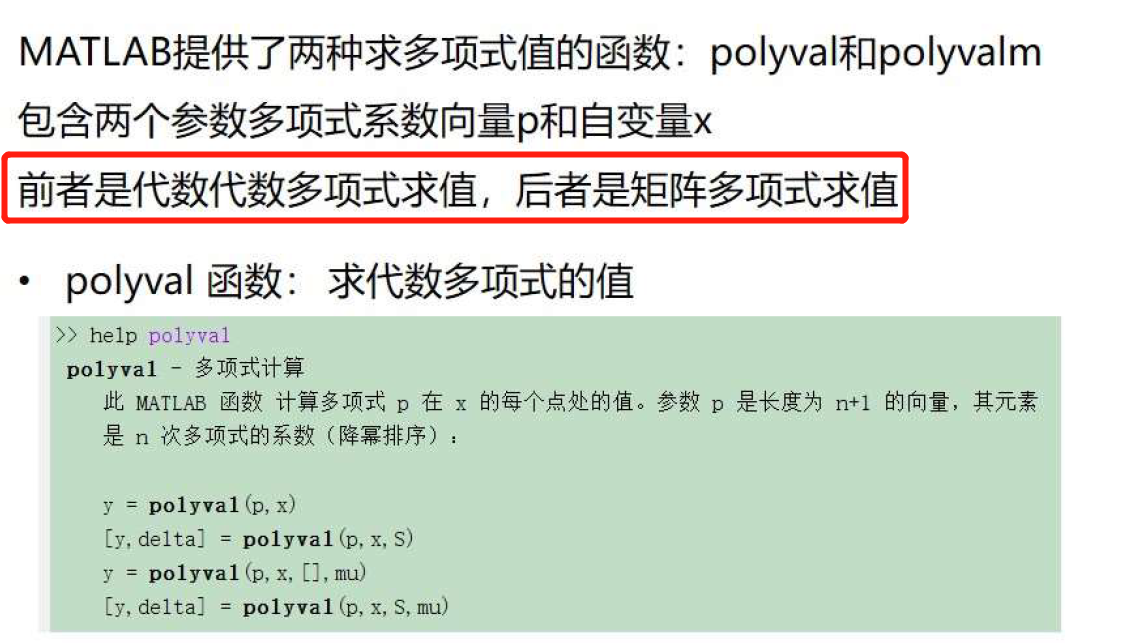

A = [1,6,0,0,-9];
poly2sym(A)

$$ans = x^{4}+6\,x^{3}-9$$

% x是变量的值
x = 1.3;
y1 = polyval(A,x)

y1 = 7.0381

% B是变量矩阵
B = [-1,1.3,1.5;2,-1.8,-1.6];
y2 = polyval(A,B)

y2 =   -14.0000    7.0381   16.3125
   55.0000  -33.4944  -27.0224


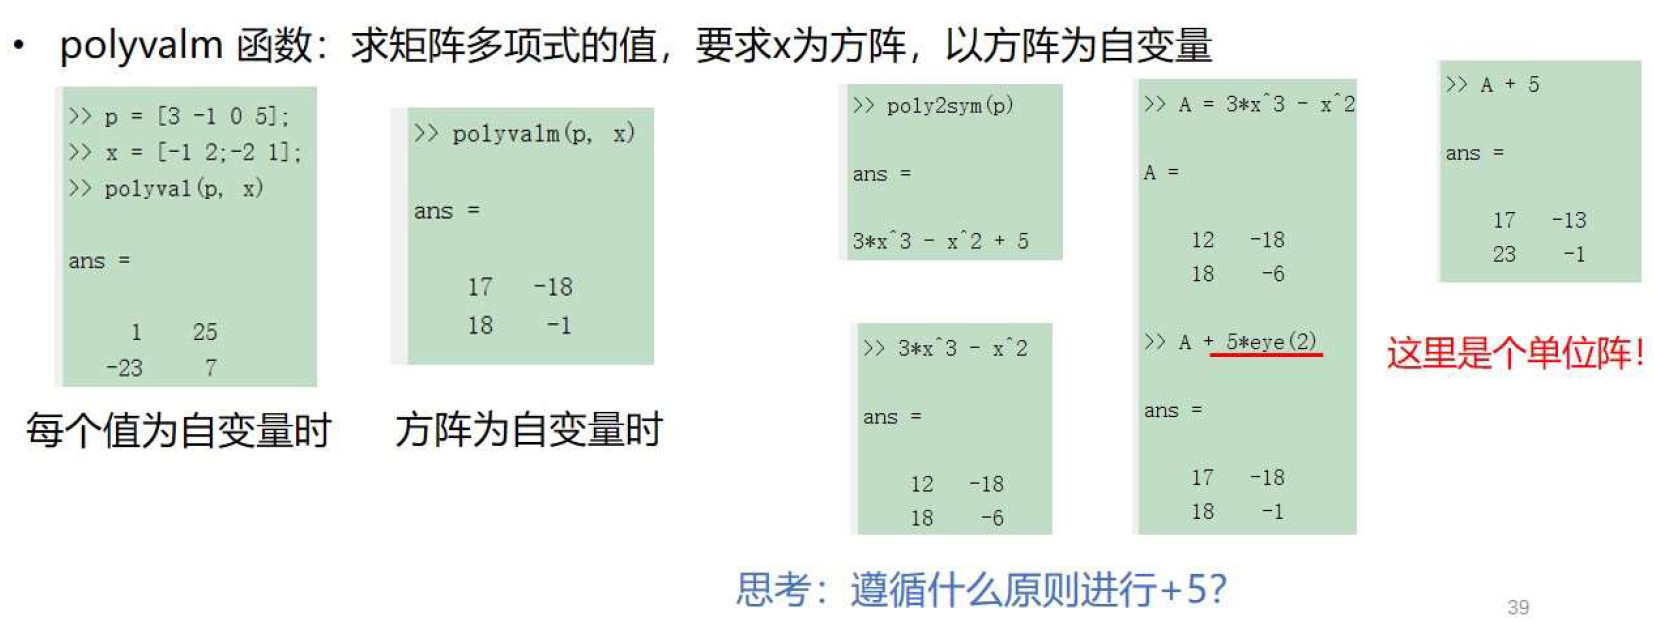

% 求矩阵多项式的值，要求x为方阵，以方阵为自变量
p = [3,-1,0,5];
poly2sym(p)

$$ans = 3\,x^{3}-x^{2}+5$$

x = [-1,2;-2,1];
polyval(p,x)

ans =      1    25
   -23     7


polyvalm(p,x)

ans =     17   -18
    18    -1


**求根**

% 求根
p = [1,2,1];
poly2sym(p)

$$ans = x^{2}+2\,x+1$$

r = roots(p)

r =     -1
    -1


% 如果知道了多项式的全部根，可以用poly函数建立该多项式
poly(r)

ans =      1     2     1
